# Animation Project

Reads in main image

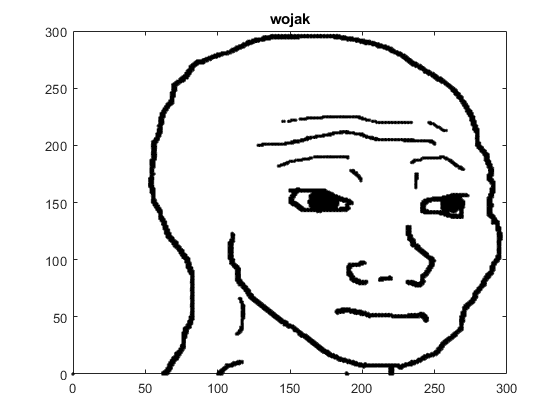

wojak = imread('wojak.jpg');
wojakOut = Jpeg2pointsConverter(wojak, 200);
title('wojak')

Adds extra points to be compatable with the image that will be morphed into

vector = [137; 296];    % arbitrary point in image
ExtraPts = vector * ones(1,9);
wojakOut = [wojakOut(:, 1:9), ExtraPts, wojakOut(:, 10:end)];

Reads in morphed image

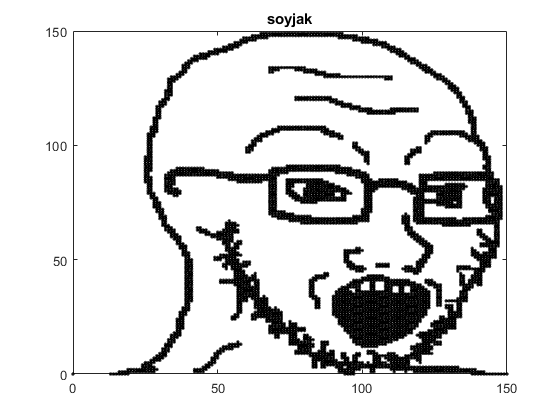

soyjak = imread("soyjak.jpg");
soyjakOut = Jpeg2pointsConverter(soyjak, 33); 
title('soyjak')

 Waits for user to start animation

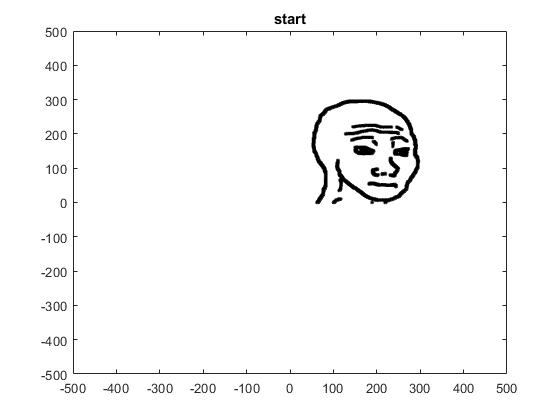

fill(wojakOut(1, :), wojakOut(2, :), 'white.')
axis([-500 500 -500 500])
title("start")

pause()

First transformation is a shift left and a shift down

Shift left 150

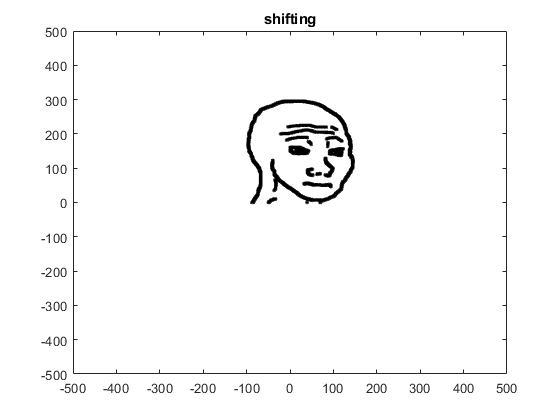

[m, n] = size(wojakOut);
vector = [-1; 0];   % shift in negative x direction
Shift = vector * ones(1, n);
for j = 1:150
    wojakOut = wojakOut + Shift;
end
fill(wojakOut(1, :), wojakOut(2, :), 'white.')
axis([-500 500 -500 500])
title("shifting")
pause(0.5)

Shift down 150

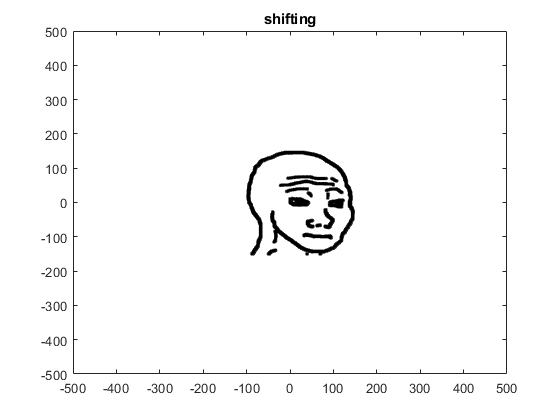

vector = [0; -1];   % shift in negative y direction
Shift = vector * ones(1, n); 
for j = 1:150
    wojakOut = wojakOut + Shift;
end
fill(wojakOut(1, :), wojakOut(2, :), 'white.')
axis([-500 500 -500 500])
title("shifting")
pause(0.5)

Next transformation is a rotation

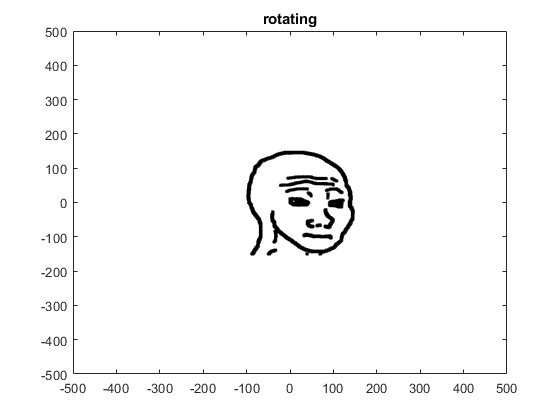

transformationMatrix = [cos(pi/32), sin(pi/32); -sin(pi/32), cos(pi/32)]; % rotation
for i = 1:64
    wojakOut = transformationMatrix * wojakOut;
    fill(wojakOut(1, :), wojakOut(2, :), 'white.')
    axis([-500 500 -500 500])
    title("rotating")
    pause(0.0001);
end

Next transformation is a shear in both positive and negative x direction

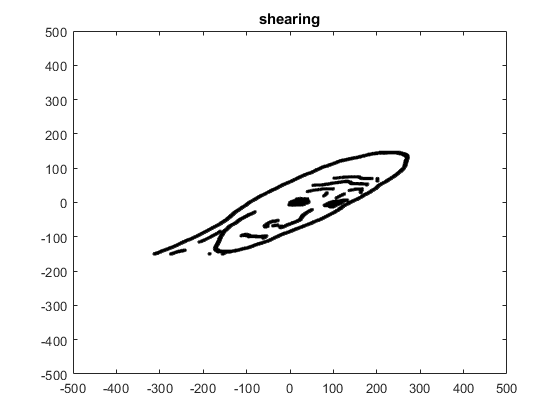

transformationMatrix = [1 1.5; 0 1];  % shear
wojakNew = transformationMatrix * wojakOut;
fill(wojakNew(1, :), wojakNew(2, :), 'white.')
axis([-500 500 -500 500])
title("shearing")
pause(0.5);

Shear back to normal

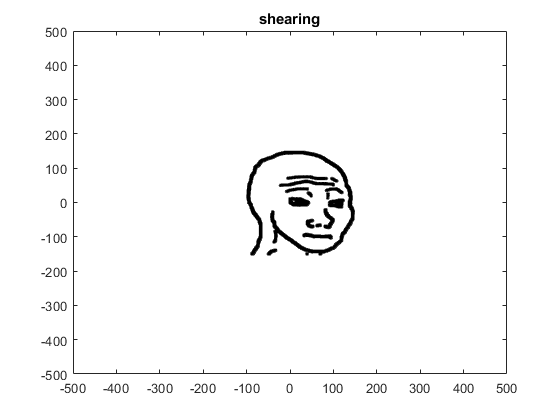

transformationMatrix = [1 -1.5; 0 1]; % shear
wojakNew = transformationMatrix * wojakNew;
fill(wojakNew(1, :), wojakNew(2, :), 'white.')
axis([-500 500 -500 500])
title("shearing")
pause(0.5);

Shear in both positive and negative y directions

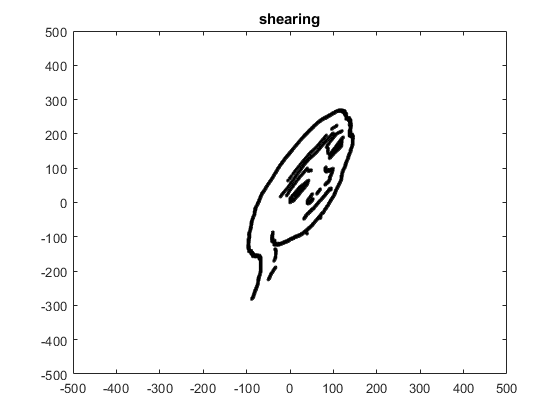

transformationMatrix = [1 0; 1.5 1];  % shear
wojakNew = transformationMatrix * wojakOut;
fill(wojakNew(1, :), wojakNew(2, :), 'white.')
axis([-500 500 -500 500])
title("shearing")
pause(0.5);

Now to morph correctly, the morphed image must be put where the image already is while also being the same size

First, the morph image gets scaled up to the size of the image

transformationMatrix = [2 0; 0 2];    % scale
soyjakOut = transformationMatrix * soyjakOut;
[m, n] = size(soyjakOut);

Next, the morphed image gets shifted to where the image is

vector = [-1; 0];   % shift in negative x direction
Shift = vector * ones(1, n); 
for j = 1:150
    soyjakOut = soyjakOut + Shift;  
end
vector = [0; -1];   %shift in negative y direction
Shift = vector * ones(1, n); 
for j = 1:150
    soyjakOut = soyjakOut + Shift;  
end

Now the morphing can happen

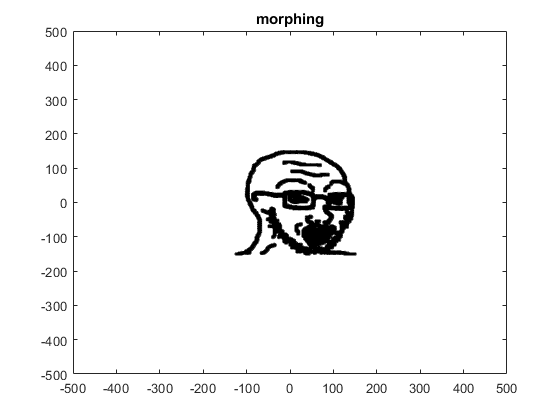

for x = 0:1/8:1
	wojakOut = (1 - x) * wojakOut + x * soyjakOut;
	fill(wojakOut(1, :), wojakOut(2, :), 'white.')
    axis([-500 500 -500 500])
    title("morphing")
	pause(0.25);
end

For the next transformation, the image will be reflected along the line x = 0

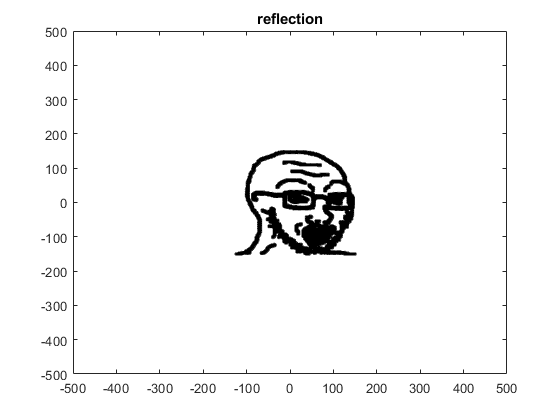

fill(wojakOut(1, :), wojakOut(2, :), 'white.')
axis([-500 500 -500 500])
title("reflection")
pause(0.5);

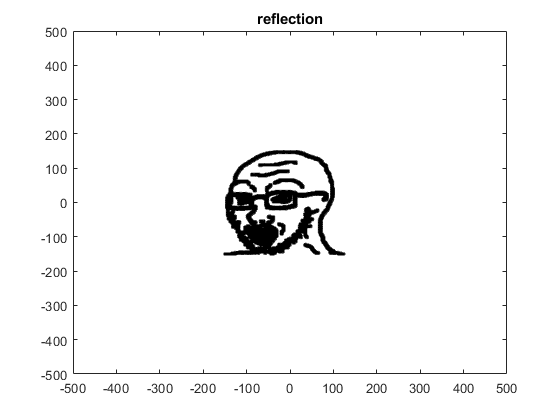

transformationMatrix = [-1 0; 0 1];   % reflection across y-axis
wojakOut = transformationMatrix * wojakOut;
fill(wojakOut(1, :), wojakOut(2, :), 'white.')
axis([-500 500 -500 500])
title("reflection")

pause(0.5);

To notice the function working correctly, the image must be moved away from the origin

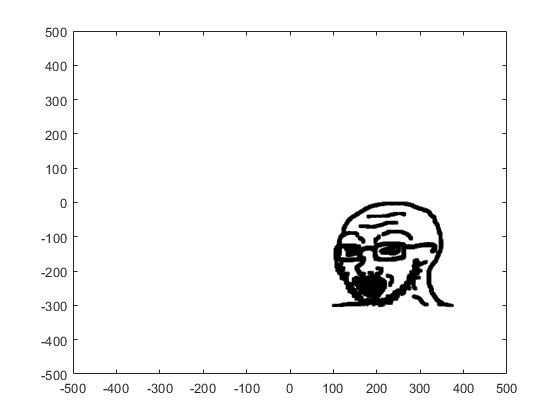

vector = [1; 0];    % shift in positive x direction
Shift = vector * ones(1, n); 
for j = 1:250
    wojakOut = wojakOut + Shift;  
end
vector = [0; -1];   % shift in negative y direction
Shift = vector * ones(1, n); 
for j = 1:150
    wojakOut = wojakOut + Shift;  
end
fill(wojakOut(1, :), wojakOut(2, :), 'white.')
axis([-500 500 -500 500])
pause(0.5)

The function is called. The definition is at the bottom of the file

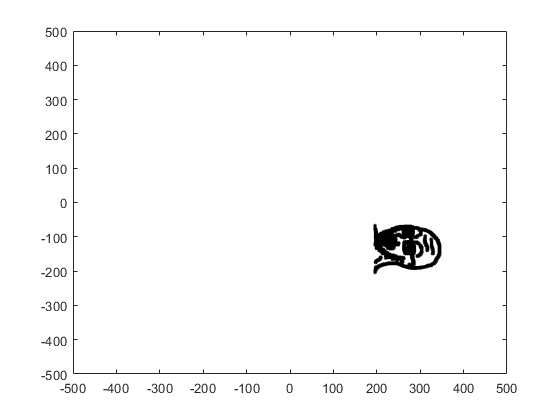

wojakOut = partd(wojakOut);

To make it seem the image is walking off the edge of the screen, the image is shifted in one direction many times

[m, n] = size(wojakOut);
vector = [0; 1];    % Shift in positive y direction
Shift = vector * ones(1, n);
for y = 0:14  % 14 'steps'
    for j = 1:50  % each 'step' is 50
        wojakOut = wojakOut + Shift; 
        fill(wojakOut(1, :), wojakOut(2, :), 'white.')
        axis([-500 500 -500 500])
        title("walking")
    end
    pause(0.01)
end

Animation is done

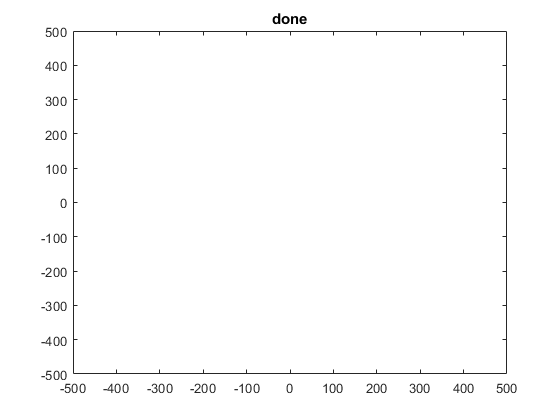

title("done")

Function scales down character by 50% and rotates clockwise 90 degrees

function output = partd(character)

    % remember coordinates
    xcoord = character(1, 1); 
    ycoord = character(2, 1);

    % send to origin(shift in x and y directions)
    xcoords = character(1, :);
    ycoords = character(2, :);
    character(1, :) = xcoords - xcoord;
    character(2, :) = ycoords - ycoord + 150;

    % transform(scale and rotate)
    transformationMatrix = [0.5, 0; 0 0.5];   % scale
    character = transformationMatrix * character;

    fill(character(1, :), character(2, :), 'white.')
    axis([-500 500 -500 500])

    transformationMatrix = [cos(pi / 32), sin(pi / 32); -sin(pi / 32), cos(pi / 32)]; % rotation
    for i = 1:16
        character = transformationMatrix * character;
    end

    % move back to coordinates
    character(1, :) = character(1, :) + xcoord;
    character(2, :) = character(2, :) + ycoord - 150;

    fill(character(1, :), character(2, :), 'white.')
    axis([-500 500 -500 500])

    % return
    output = character;
    return;
end 